# Metoda Duforta - Frankla


clear,clc,close all
format long
L=1;%in mm
tk=600;%in s
D=0.0000611;
teta=0.7;
%%
dx=0.05;
dt=20;
x=0:dx:L;
t=0:dt:tk;
x_val=length(x);
x_end=max(x);
t_val=length(t);
r=D*dt/dx^2;
%%BC
t0_bc=sin(2*pi*x);
t0_bc=@(x) sin(2*pi*x)

t0_bc = function_handle with value:
    @(x)sin(2*pi*x)


%t0_bc=@(x) x.^2-4.*x;
x0_bc=0;
xe_bc=0;
%% mapping
for n=1:t_val;
    for i=1:x_val;
        if x(i)==0
            A(n,i)={[[t(n)] [x(i)]  [x0_bc]]};
        elseif x(i)==x_end
            A(n,i)={[[t(n)] [x(i)]  [xe_bc]]};
        elseif t(n)==0
            A(n,i)={[[t(n)] [x(i)]  [t0_bc(x(i))]]};
        else
            A(n,i)={[[t(n)] [x(i)]  [NaN]]};
        end
    end
end


for n=2
    B=(1/r+2*teta)*eye(x_val-2)+diag((-teta)*ones(1,x_val-3),1)
    +diag((-teta)*ones(1,x_val-3),-1);
        for i=2:x_val-1
            bc(i-1,1)=(1-teta)*A{n-1,i-1}(3)+(1/r-2+2*teta)*A{n-1,i}(3)
            +(1-teta)*A{n-1,i+1}(3);
        end
        bc(1)=bc(1)+A{n,1}(3);
        bc(length(bc))=bc(length(bc))+A{n,x_val}(3);
        val=inv(B)*bc;
        for k=1:length(val)
            A{n,k+1}(3)=val(k);
        end
end
for n=3:t_val
        B=(1+2*r)*eye(x_val-2);
        for i=2:x_val-1
            bc(i-1,1)=(1-2*r)*A{n-2,i}(3)+2*r*A{n-1,i-1}(3)+2*r*A{n-1,i+1}(3);
        end
        bc(1)=bc(1)+A{n,1}(3);
        bc(length(bc))=bc(length(bc))+A{n,x_val}(3);
        val=inv(B)*bc;
        for k=1:length(val)
            A{n,k+1}(3)=val(k);
        end
end


o=1;
for n=2:t_val
    for i=2:x_val-1
        if isempty(A{n,i})==0
            t_final(o,1)=A{n,i}(1);
            x_final(o,1)=A{n,i}(2);
            epsilon_final(o,1)=A{n,i}(3);
            o=o+1;
        end
    end
end
for n=2:t_val
    for i=2:x_val-1
        eps_mesh(n-1,i-1)=A{n,i}(3);
    end
end
ttable=table([t_final],[x_final],[epsilon_final])

ttable = 570×3 table
    t_final    x_final       epsilon_final    
    _______    _______    ____________________

      20        0.05         0.294710576903168
      20         0.1         0.560572829169724
      20        0.15         0.771562307176583
      20         0.2         0.907025890766301
      20        0.25         0.953703460546831
      20         0.3         0.907025890766301
      20        0.35         0.771562307176583
      20         0.4         0.560572829169724
      20        0.45         0.294710576903168
      20         0.5      4.39290420357227e-17
      20        0.55        -0.294710576903168
      20         0.6        -0.560572829169723
      20        0.65        -0.771562307176583
      20         0.7        -0.907025890766301
      20        0.75        -0.953703460546831
      20         0.8        -0.907025890766301


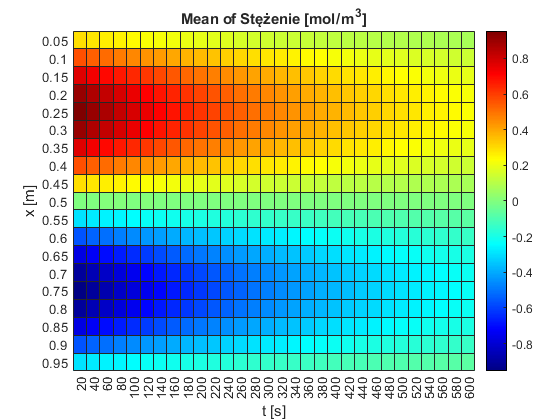

h =   HeatmapChart (Mean of Stężenie [{mol}/{m{^3}}]) with properties:

      SourceTable: [570×3 table]
        XVariable: 't [s]'
        YVariable: 'x [m]'
    ColorVariable: 'Stężenie [{mol}/{m{^3}}]'
      ColorMethod: 'mean'

  Show all properties


ttable = renamevars(ttable,["t_final","x_final","epsilon_final"], ...
    ["t [s]","x [m]","Stężenie [{mol}/{m{^3}}]"]);
h = heatmap(ttable,'t [s]','x [m]','ColorVariable', ...
    'Stężenie [{mol}/{m{^3}}]','Colormap',jet)

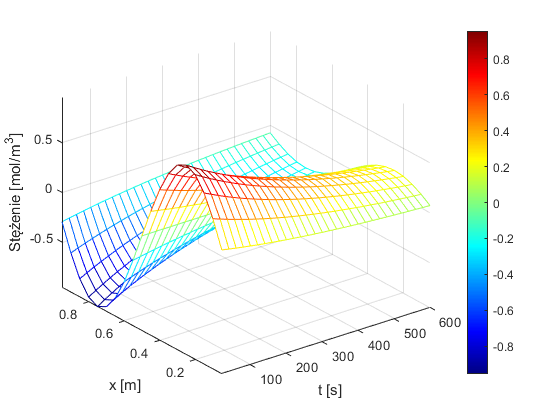

mesh(t(2:end),x(2:end-1),transpose(eps_mesh))
colormap(jet)
colorbar
% title('Dufort - Frankel method for Diffusion Equation')
axis tight
xlabel('t [s]') 
ylabel('x [m]')
zlabel('Stężenie [{mol}/{m{^3}}]')

o=1;
for n=2:length(t)
    for i=2:length(x)-1
        ana(n-1,i-1)=sin(2*pi*x(i))*exp(-4*pi^2*D*t(n));
        ana_final(o,1)=sin(2*pi*x(i))*exp(-4*pi^2*D*t(n));
        o=o+1;
    end
end
atable=table([t_final],[x_final],[ana_final])

atable = 570×3 table
    t_final    x_final         ana_final      
    _______    _______    ____________________

      20        0.05         0.294463084959565
      20         0.1         0.560102071518336
      20        0.15          0.77091436485629
      20         0.2         0.906264188885892
      20        0.25         0.952902559793449
      20         0.3         0.906264188885892
      20        0.35          0.77091436485629
      20         0.4         0.560102071518336
      20        0.45         0.294463084959565
      20         0.5      1.16696906975037e-16
      20        0.55        -0.294463084959566
      20         0.6        -0.560102071518336
      20        0.65        -0.770914364856289
      20         0.7        -0.906264188885892
      20        0.75        -0.952902559793449
      20         0.8        -0.906264188885892


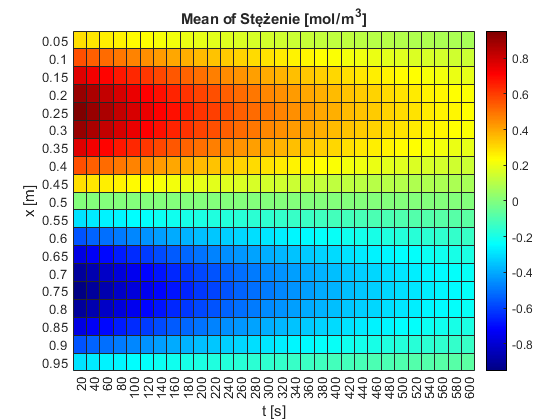

h2 =   HeatmapChart (Mean of Stężenie [{mol}/{m{^3}}]) with properties:

      SourceTable: [570×3 table]
        XVariable: 't [s]'
        YVariable: 'x [m]'
    ColorVariable: 'Stężenie [{mol}/{m{^3}}]'
      ColorMethod: 'mean'

  Show all properties


atable = renamevars(atable,["t_final","x_final","ana_final"], ...
    ["t [s]","x [m]","Stężenie [{mol}/{m{^3}}]"]);
h2 = heatmap(atable,'t [s]','x [m]','ColorVariable', ...
    'Stężenie [{mol}/{m{^3}}]','Colormap',jet)

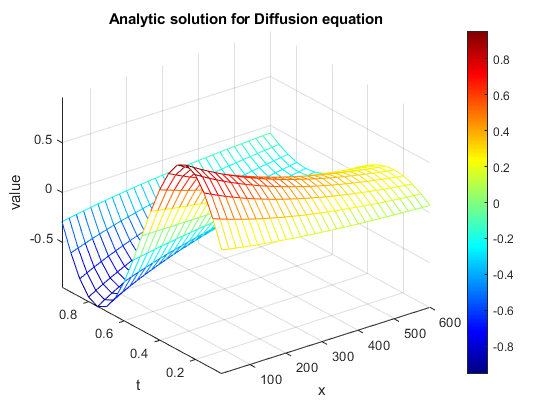

mesh(t(2:end),x(2:end-1),transpose(ana))
colormap(jet)
axis tight
xlabel('x') 
ylabel('t')
zlabel('value')
title('Analytic solution for Diffusion equation')
colormap(jet)
colorbar


error=abs(eps_mesh-ana);
mesh(t(2:end),x(2:end-1),transpose(error))
colormap(jet)
axis tight
xlabel('t [s]') 
ylabel('x [m]')
zlabel('Wartość błędu')
name=sprintf('Błąd metody DFFR, dx= %2.3f,dt= %2.0f',dx,dt)

name = 'Błąd metody DFFR, dx= 0.050,dt= 20'

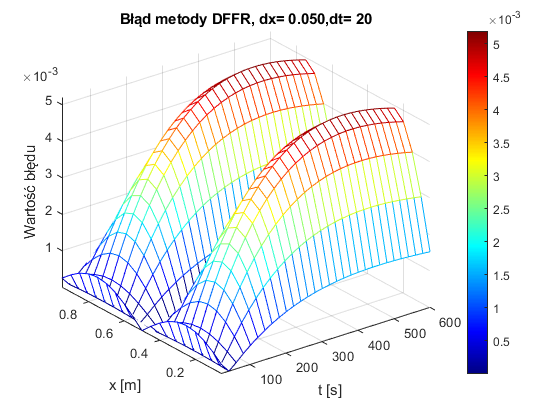

title(name)
colormap(jet)
colorbar

error_norm2=norm(error,'fro')

error_norm2 =    0.073163503431821
